addpath myFunction\myftn\
clearvars -except Gfinal0T ImgFinalZnorm vm x y Zfinal0T
;close;clc

fn = "RawData\1T-TaS2(point defect)\Gxy0T.mat"

fn = "RawData\1T-TaS2(point defect)\Gxy0T.mat"

loadif(fn)

fldNm = 6×1 cell array
    {'ImgFinalZnorm'}
    {'vm'           }
    {'Gfinal0T'     }
    {'Zfinal0T'     }
    {'y'            }
    {'x'            }



Your variables are:

fldNm  fn     mt     



ans = 'already'

margins = [700 770]

margins =    700   770


Visible on

gr  = groot();
gr.Units = "normalized";
mp = gr.MonitorPositions;
f1 = figure(1);
f1.Units  = "normalized";
f1.Position = secondNormalization(mp(1,:),[0 0 1 1]);
f1.Visible = "on";

subplotting

msb = 3

msb = 3

nsb = 5

nsb = 5

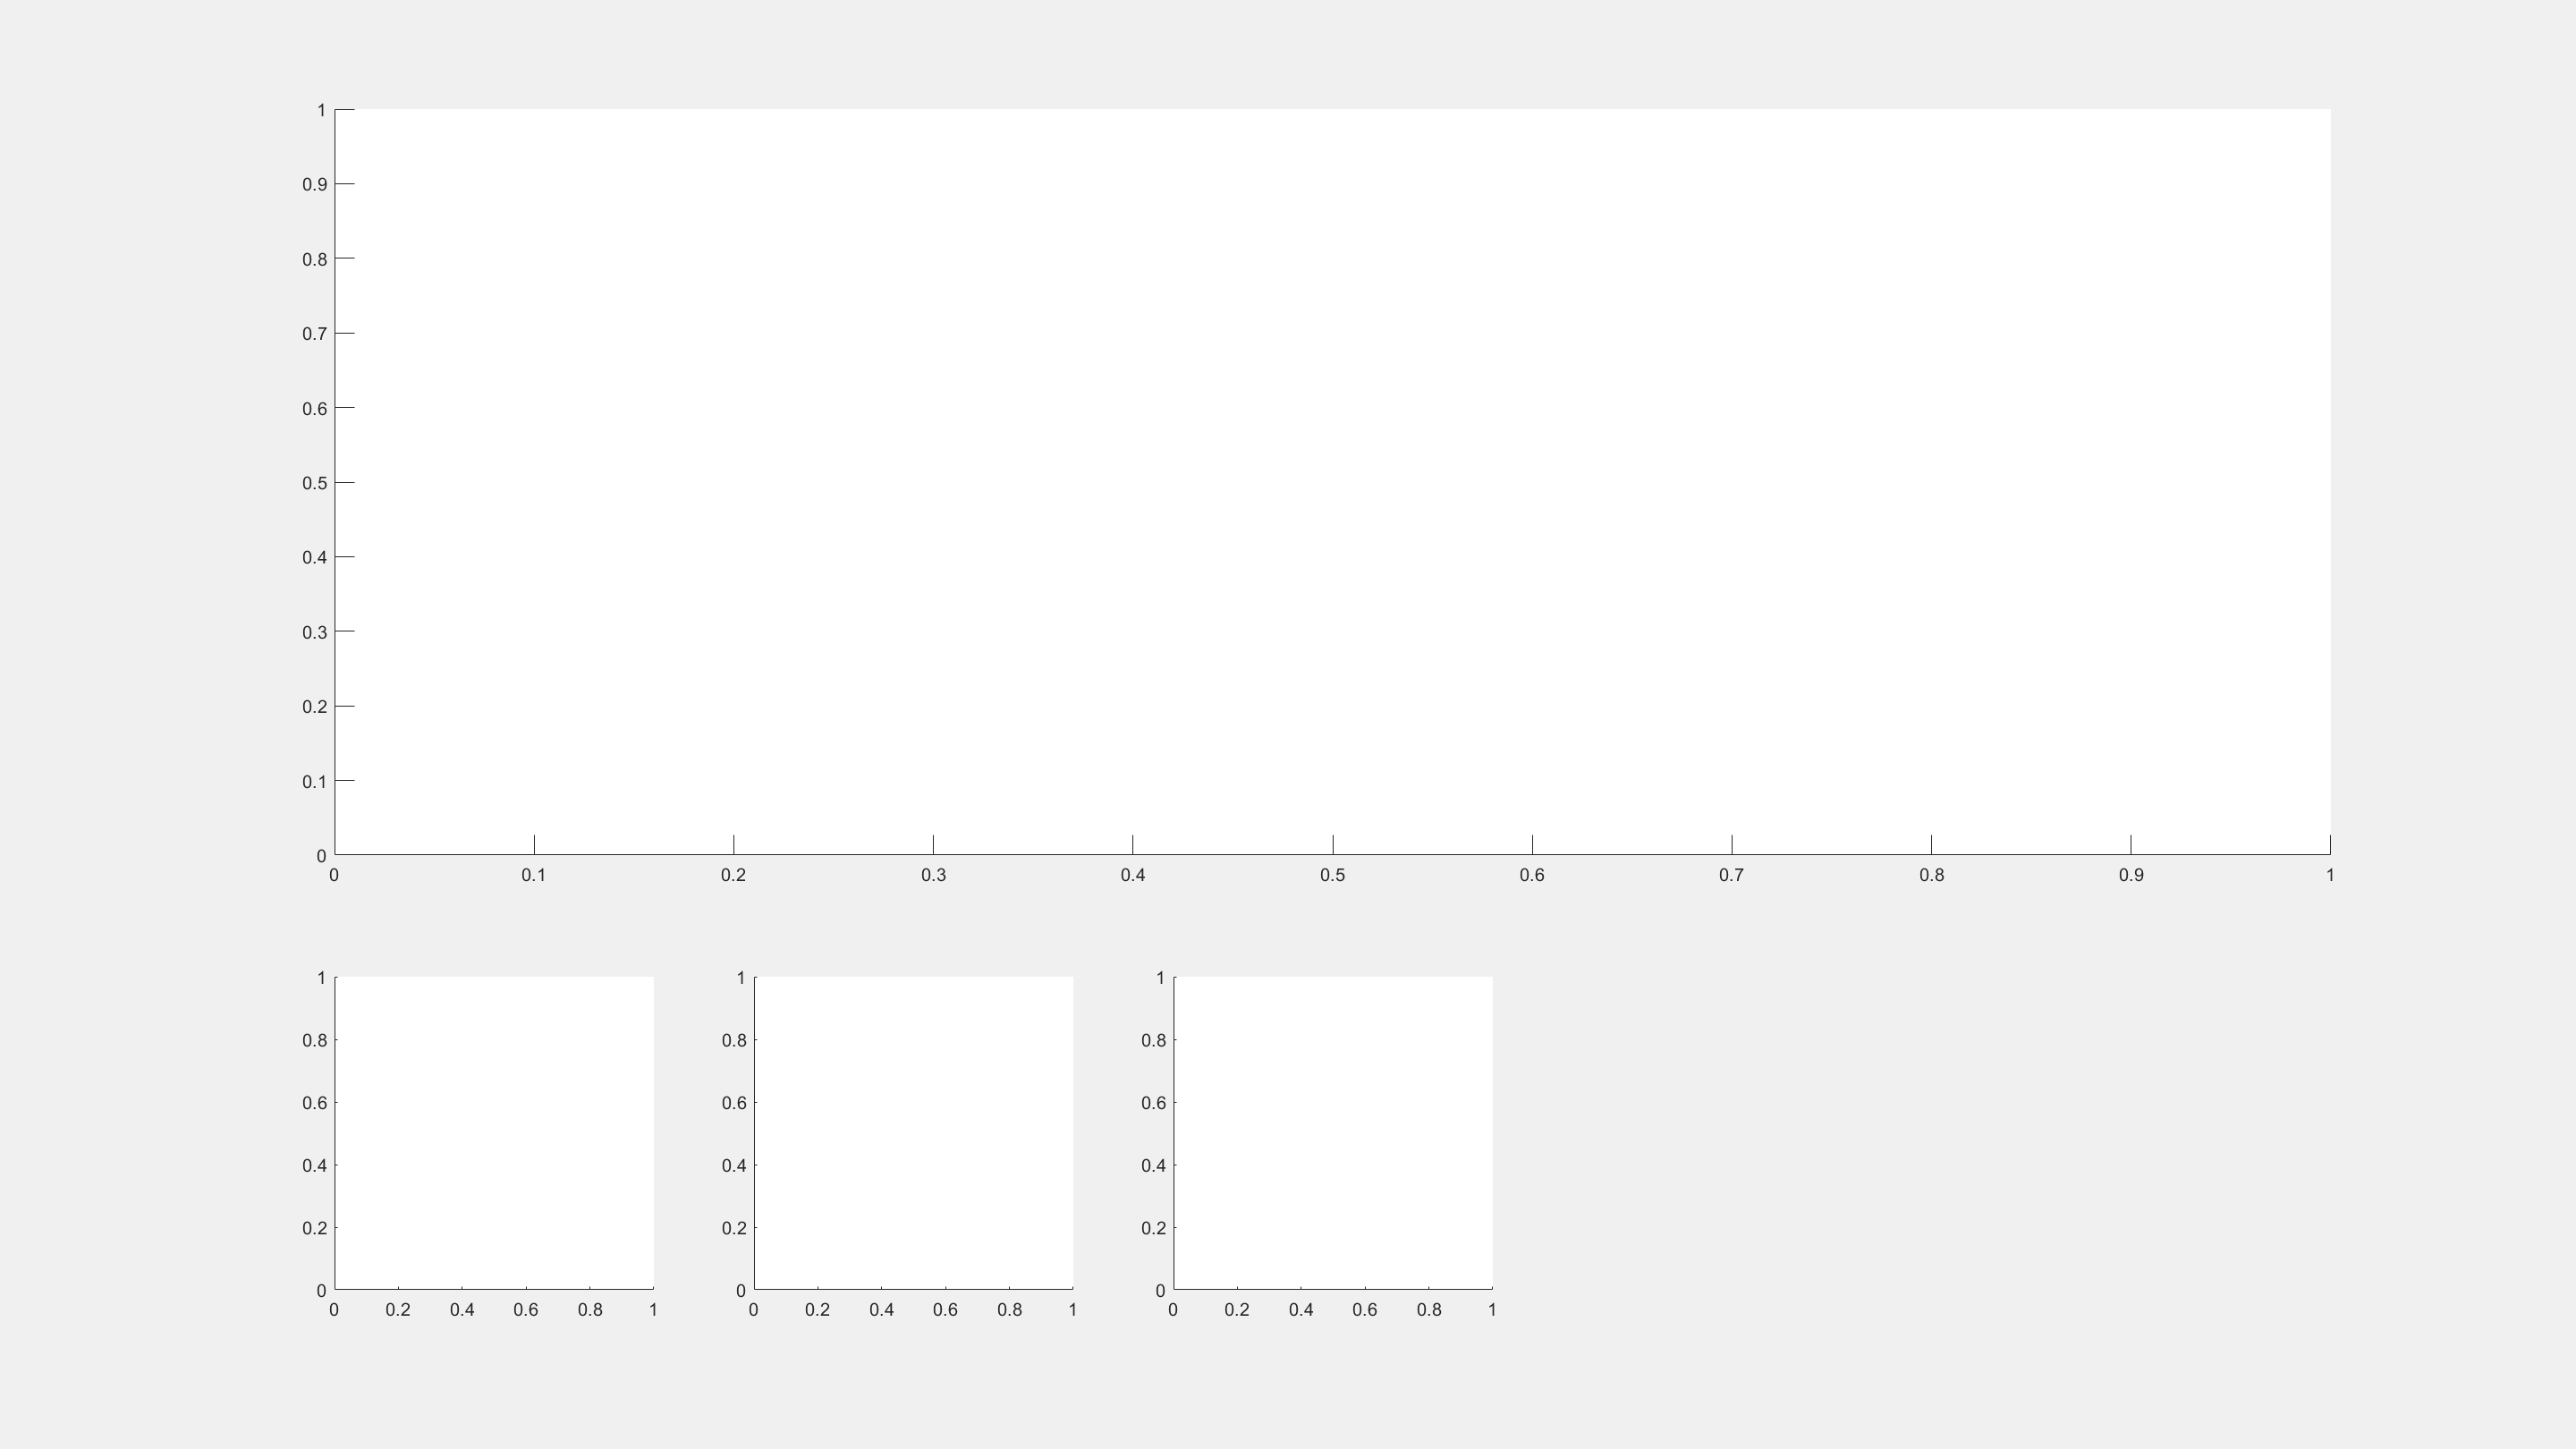

axReal = subplot(msb,nsb,1:10,'Tag','axReal');
axDos = subplot(msb,nsb,11,'Tag','axDos');
axHis = subplot(msb,nsb,12,'Tag','axHis');
axZoom = subplot(msb,nsb,13,'Tag','axZoom');

rngs = [1 margins(1);margins(2) size(Gfinal0T,1)];

whichDm = 1

whichDm = 1

imgInfo = 2

imgInfo = 2

iv = 258%1

iv = 258

xpxl = 320

xpxl = 320

ypxl = 318

ypxl = 318

vNow = vm(iv)

vNow = -0.5030

DataProcessing(dependent on )

rng = rngs(whichDm,:);
G = Gfinal0T(rng(1):rng(2),:,:);%%%%% 속도 결정 단계
Z = ImgFinalZnorm(rng(1):rng(2),:,:);%
g_at = squeeze(G(xpxl,ypxl,:));
gavg = squeeze(mean(mean(G)));

## Graphic

### Initial Graphic Elements

Topography

f1.CurrentAxes = axReal

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0.0029 1.7500 0.7500 0.7500]
       Units: 'normalized'

  Show all properties


imgRegion(G,Z,imgInfo,iv)
hold on
highlightPts(xpxl,ypxl)
hold off

Zoomed Topography

f1.CurrentAxes = axZoom

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0.0029 1.7500 0.7500 0.7500]
       Units: 'normalized'

  Show all properties


xrng = (-20:20) +xpxl;
yrng = (-20:20) + ypxl;
imgRegion(G(xrng,yrng,:),Z(xrng,yrng),imgInfo,iv)



Point STS

f1.CurrentAxes = axDos

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0.0029 1.7500 0.7500 0.7500]
       Units: 'normalized'

  Show all properties


% V 
plot(vm,g_at)
hold on
plot(vm,gavg)
hold off
xline(vm(iv))
xlim([-1 1]*.6)
legend(["point" "Averaged"])
xlabel('V (V)')
ylabel('Averaged LDOS (Arb)')

Histogram at specific Energy

f1.CurrentAxes = axHis

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0.0029 1.7500 0.7500 0.7500]
       Units: 'normalized'

  Show all properties


conductanceMap = G(:,:,iv);
conductanceMap = conductanceMap(:);
conductanceMap = conductanceMap(~conductanceMap==0);
histogram(conductanceMap)
xline(g_at(iv))
min(conductanceMap)

ans = -0.1336

max(conductanceMap)

ans = 0.1507

Change Pts in GUI

set(axReal.Children(2), 'ButtonDownFcn', @(src,event) changePts(src,event,G,Z,imgInfo,iv));


Change Pts in GUI


% function changeE(src,event)
% src
% event
% end
% set(axDos, 'ButtonDownFcn', @changeE);

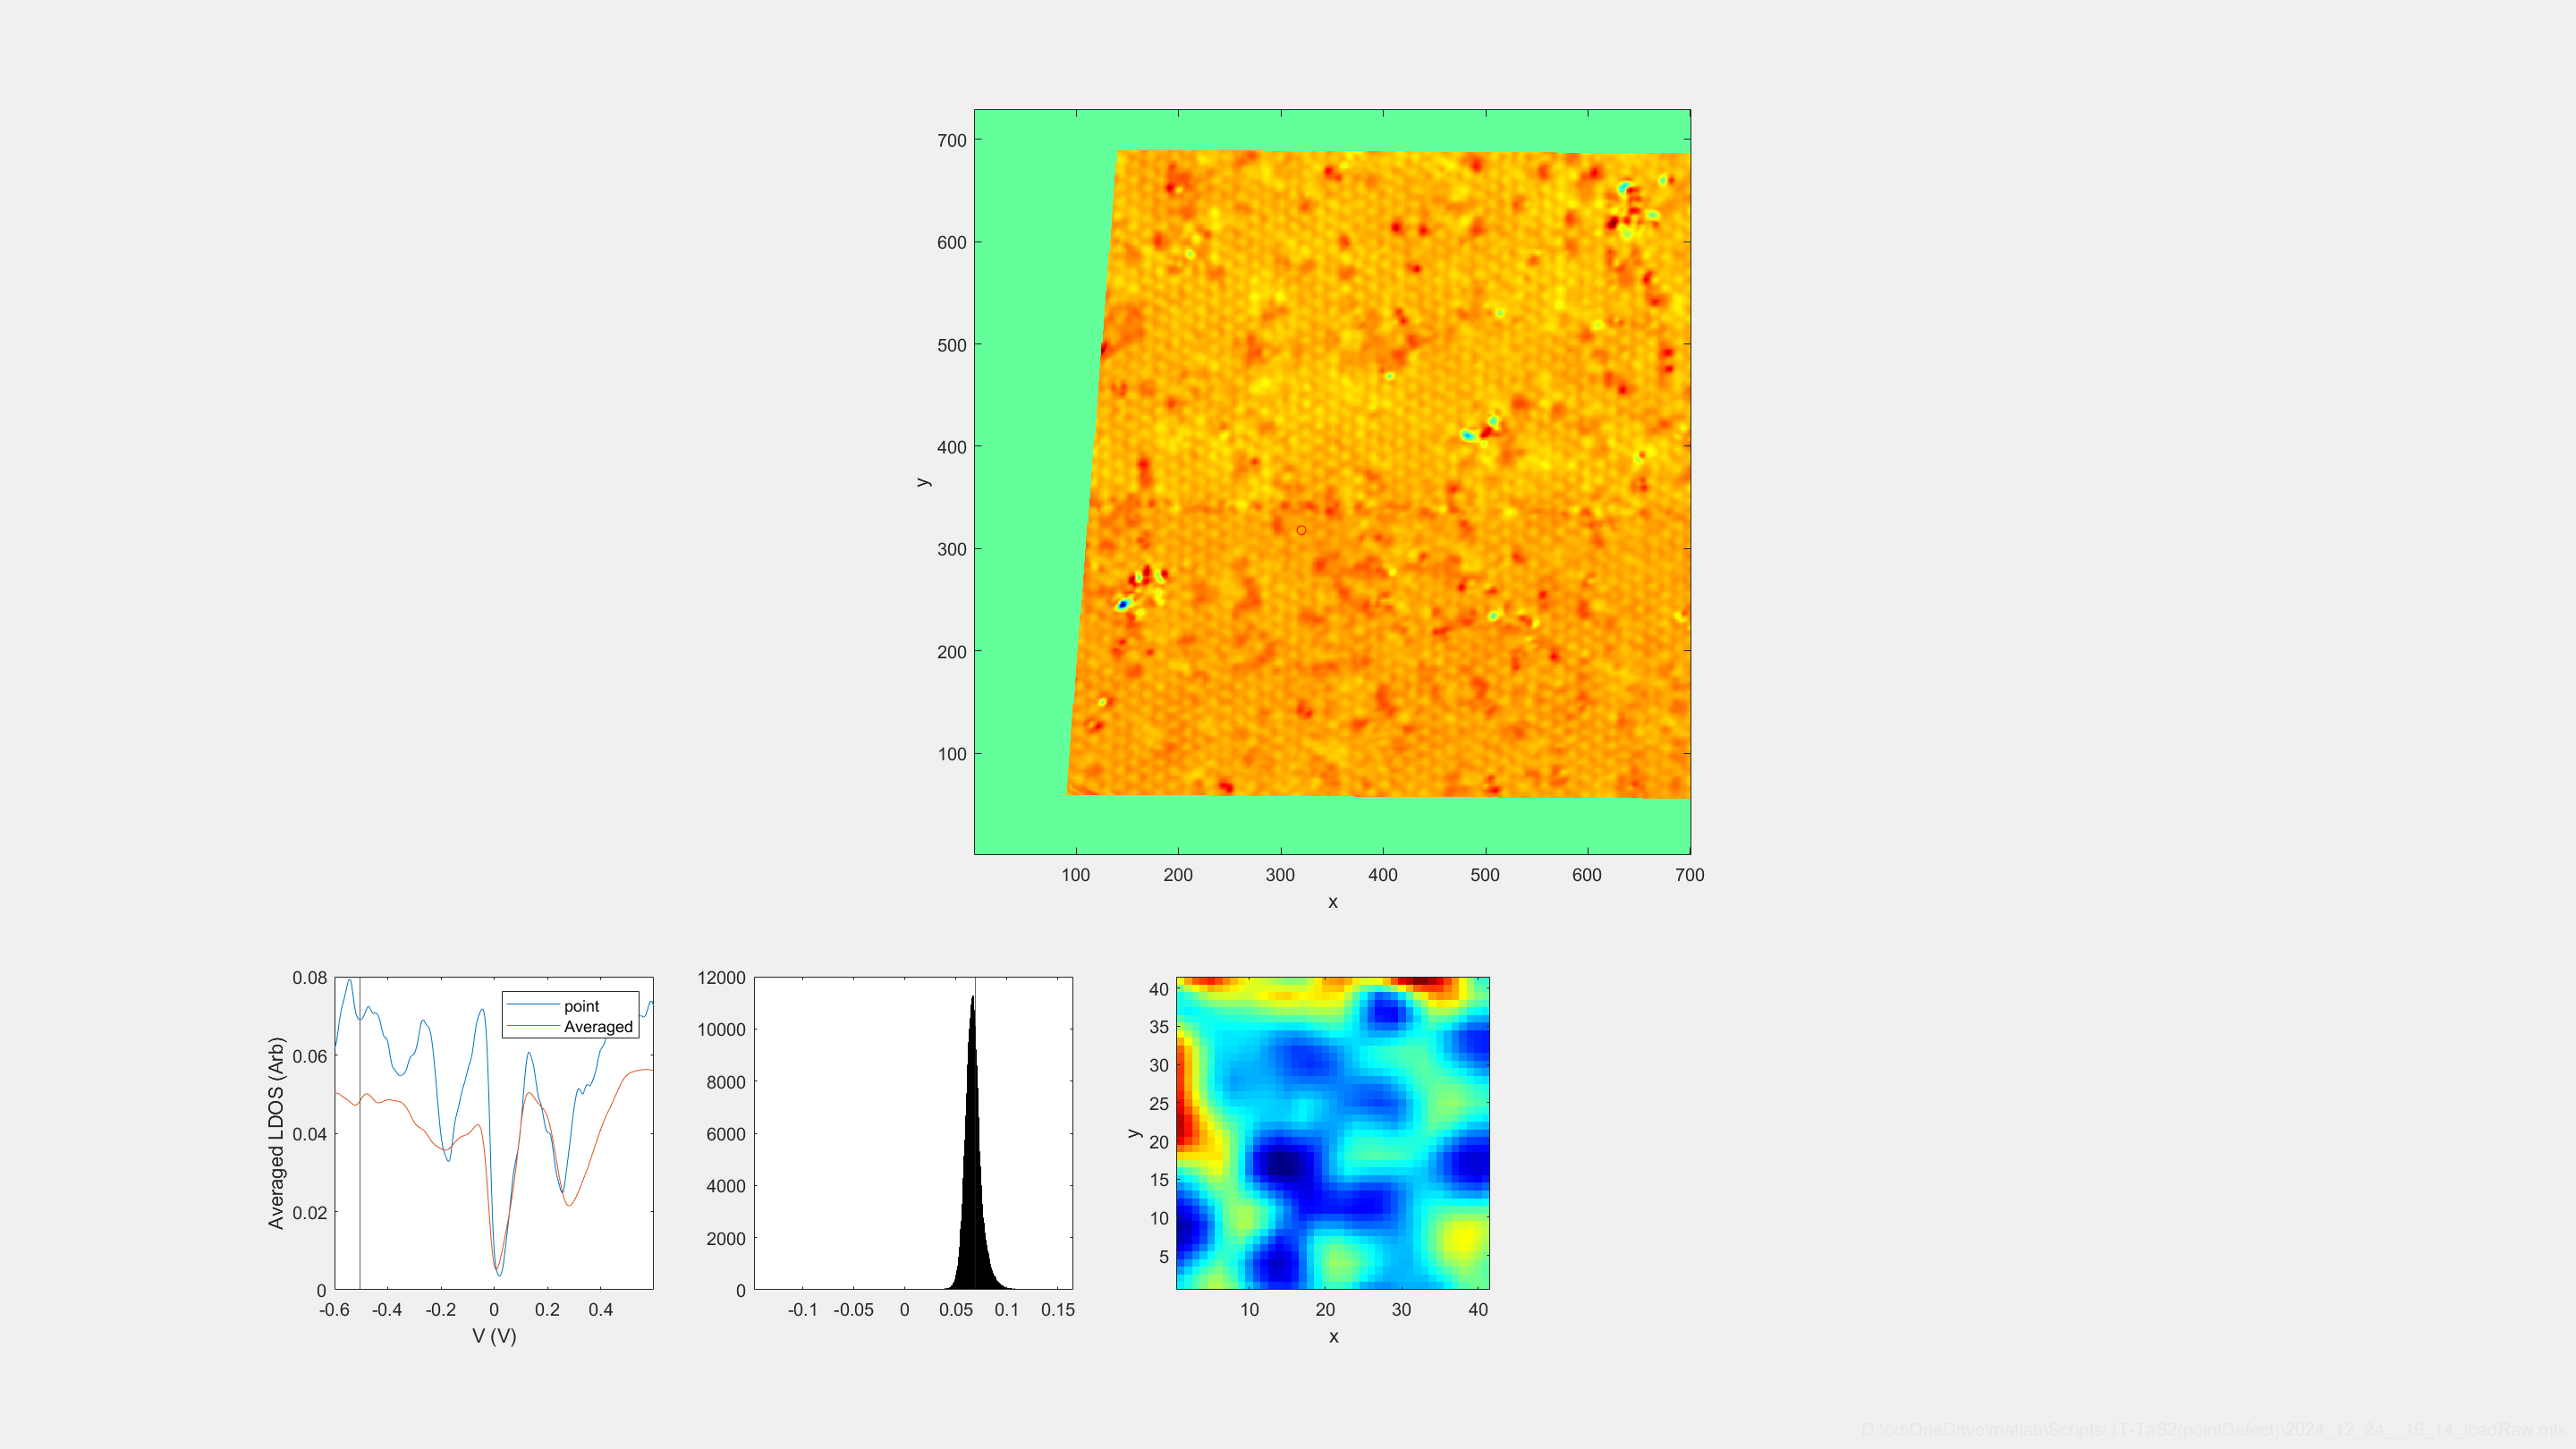

waterMark()

function changePts(src,event,G,Z,imgInfo,iv)
% src
% event
pts = round(event.IntersectionPoint);

%change red point 
gobj = findobj('Tag','highlightPts');
gobj.XData = pts(1);
gobj.YData = pts(2);

%change point ldos
g_at = squeeze(G(xpxl,ypxl,:));



%change zoom
f1 = gcf;
f1.CurrentAxes = findobj('Tag','axZoom');
xrng = (-20:20) + pts(1);
yrng = (-20:20) + pts(2);
imgRegion(G(xrng,yrng,:),Z(xrng,yrng),imgInfo,iv);
end

function imgRegion(G,Z,imgInfo,iv)
if imgInfo == 1
    imgfoo = Z;
elseif imgInfo == 2
    imgfoo = G(:,:,iv);
end

imagesc(imgfoo');
axis image;
ax = gca;
ax.YDir = 'normal';

xlabel('x');
ylabel('y');
if imgInfo == 1
    colormap gray;



elseif imgInfo == 2
    colormap jet;
end

% hold on
% plot(xpxl,ypxl,'ro','MarkerSize',5)
end

function highlightPts(xpxl,ypxl)
plot(xpxl,ypxl,'ro','MarkerSize',5,'Tag','highlightPts')
end